addpath('~/uni/utils')

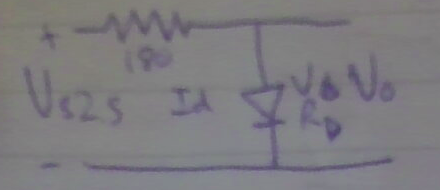

syms V_t n I_d R V_s R_d V_dd I_sat V_d I_dq

incremental_resistance = R_d == n * V_t / I_dq

$$incremental\_resistance = R_{d}=\frac{V_{t}\,n}{I_{\mathrm{dq}}}$$

diode_voltage = V_d == I_d * R_d + V_dd

$$diode\_voltage = V_{d}=V_{\mathrm{dd}}+I_{d}\,R_{d}$$

kvl = V_s == I_d * R + V_d

$$kvl = V_{s}=V_{d}+I_{d}\,R$$

diode_characteristic = I_sat * (exp(V_d / (n * V_t)) - 1) == I_d

$$diode\_characteristic = I_{\mathrm{sat}}\,\left({\mathrm{e}}^{\frac{V_{d}}{V_{t}\,n}}-1\right)=I_{d}$$


constants = [
    V_t == 25e-3
    n == 1.5
    R == 180
    V_s == 2.5];

## Part 1

part1_a = calc([V_d I_sat], [
    constants
    kvl
    diode_characteristic
    
    I_d == 10e-3
])

part1_a = struct with fields:
      V_d: 700.0000e-003
    I_sat: 78.1933e-012



% add answer to constants
constants = [constants; I_sat == part1_a.I_sat]

$$constants = \left(\begin{array}{c} V_{t}=\frac{1}{40}\\ n=\frac{3}{2}\\ R=180\\ V_{s}=\frac{5}{2}\\ I_{\mathrm{sat}}=\frac{6049915399608447}{77371252455336267181195264} \end{array}\right)$$


load_line = calc([V_s, I_d], [
    kvl
    constants
    
    V_d == 0
]);

figure; hold on

plot([0 load_line.V_s], [load_line.I_d 0])
xlabel('V_s')
ylabel('I_d')

I_d2V_d = solve2fn(V_d, [
    constants
    diode_characteristic
], I_d);
I_d_sweep = linspace(0, load_line.I_d, 100)

I_d_sweep =      0.0000e+000   140.2918e-006   280.5836e-006   420.8754e-006   561.1672e-006   701.4590e-006   841.7508e-006   982.0426e-006     1.1223e-003     1.2626e-003     1.4029e-003     1.5432e-003     1.6835e-003     1.8238e-003     1.9641e-003     2.1044e-003     2.2447e-003     2.3850e-003     2.5253e-003     2.6655e-003     2.8058e-003     2.9461e-003     3.0864e-003     3.2267e-003     3.3670e-003     3.5073e-003     3.6476e-003     3.7879e-003     3.9282e-003     4.0685e-003     4.2088e-003     4.3490e-003     4.4893e-003     4.6296e-003     4.7699e-003     4.9102e-003     5.0505e-003     5.1908e-003     5.3311e-003     5.4714e-003     5.6117e-003     5.7520e-003     5.8923e-003     6.0325e-003     6.1728e-003     6.3131e-003     6.4534e-003     6.5937e-003     6.7340e-003     6.8743e-003


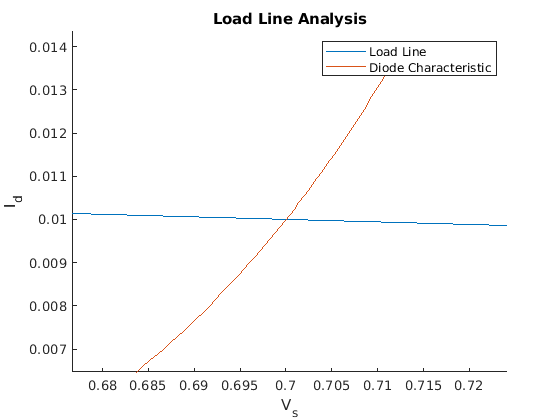


plot(I_d2V_d(I_d_sweep), I_d_sweep)
legend('Load Line', 'Diode Characteristic')
ylim([0 load_line.I_d])
title('Load Line Analysis')



part1_b = I_d2V_d([0 1 5 10 20] * 1e-3)'

part1_b =      0.0000e+000
   613.6531e-003
   674.0070e-003
   700.0000e-003
   725.9930e-003


## Part 2

part2 = calc(R_d, [
    constants
    incremental_resistance
    
    I_dq == 10e-3
])

part2 = struct with fields:
    R_d: 3.7500


## Computer Simulation

%%% Part 1
clear;

syms V_s_rms L_p L_s V_p_rms

constants = [
    % student number is n946426"3" therefore;
    V_s_rms == 13
    
    % assume source is mains power; 240vRMS
    V_p_rms == 240
]

$$constants = \left(\begin{array}{c} V_{s,\mathrm{rms}}=13\\ V_{p,\mathrm{rms}}=240 \end{array}\right)$$


winding_ratio = V_p_rms / V_s_rms == sqrt(L_p / (2 * L_s))

$$winding\_ratio = \frac{V_{p,\mathrm{rms}}}{V_{s,\mathrm{rms}}}=\sqrt{\frac{L_{p}}{2\,L_{s}}}$$


design = calc(L_s, [
    constants
    winding_ratio
    
    L_p == 1e-3
])

design = struct with fields:
    L_s: 1.4670e-006


function results_ = calc(out, eqns, vectorize)
    if ~exist('vectorize', 'var')
        vectorize = false;
    end
    
    solution = solve(eqns);
    
    % throw an error if no solution found
    assert(~any(structfun(@(sym) isempty(sym), solution)), 'no solution found. you may have too few or too many equations')
    
    results_ = struct;
    
    % keep only the fields that we want (from 'out')
    for sym = out
        symstr = string(sym);
        % and convert to double
        results_.(symstr) = double(solution.(symstr));
    end
    
    if exist('vectorize', 'var') && vectorize
        results_ = struct2array(results_);
    end
end